# Create a phase pattern for tug-of-war tweezers

This live-script attempts to reproduce the tug-of-war phase pattern from

Bezryadina et al.,  *Optical disassembly of cellular clusters by tunable ‘tug-of-war’ tweezers*.  Light: Science & Applications **volume 5, **e16158(2016), [https://doi.org/10.1038/lsa.2016.158](https://doi.org/10.1038/lsa.2016.158)

The lens is described as a combination of a prism and a cylindrical lens.  In this live-script we generate the prism using two linear gratings and we use a 1-D spherical lens for the cylindrical lens.

## Setup the workspace

addpath('../../');  % Add OTSLM to path (if not already done)
sz = [256, 256];    % Size of the simulation patterns

## Parameters describing the hologram

prism_spacing = 27  % Can't be 0

prism_spacing = 27

lens_radius = 236

lens_radius = 236

lens_scale = 20

lens_scale = 20

## Generate linear grating and lens

lin = otslm.simple.linear([sz(1), sz(2)./2], prism_spacing);
lens = otslm.simple.spherical(sz, lens_radius, 'type', '1d', 'angle_deg', 90)*lens_scale;

## Combine two linear gratings to make the prism

prism = [fliplr(lin), lin];

## Generate the TOW pattern

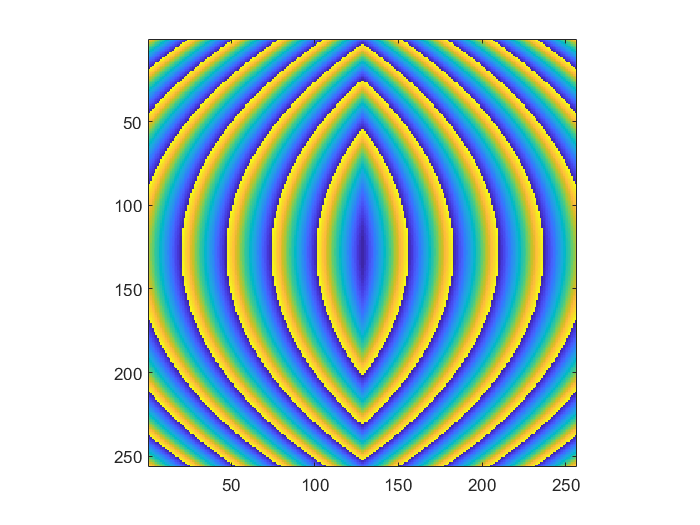

pattern = otslm.tools.finalize(lens + prism, 'device', 'slm');
imagesc(pattern)
axis image;

## About this file

This example live script is part of OTSLM.  Written by Isaac Lenton.  For further details see [https://github.com/ilent2/otslm](https://github.com/ilent2/otslm)